# Molecular graph positional encoding from SMILES

### Introduction

Unlike texts in natural language processing (NLP), nodes in a graph do not have any canonical positional information. It has been shown that Laplacian eigenvectors can be used as node positional encoding [1]. This simple example demonstrates how [MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) can work together with Python to process a [SMILES](https://en.wikipedia.org/wiki/Simplified_molecular-input_line-entry_system) database and generates positional encodings (PE) as part of graph-based transformer neural networks [2].  

### RDKit Installation

This example uses some of the fucntions from [RDKit](https://www.rdkit.org/) [3]. RDKit can be installed easily by following its [istallation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip. Make sure to give the python addess and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html).

pyenv("Version","C:\Users\...\python.exe");

As a general task, let's first clear up the workspace

clear;
clc;
close all;

### Input and draw SMILES structure

Provide the SMILES sting. We use [Anthraquinone](https://pubchem.ncbi.nlm.nih.gov/compound/Anthraquinone) as a symmetrical example. pos_enc_dim is given as the number of positional encoding vecotors.

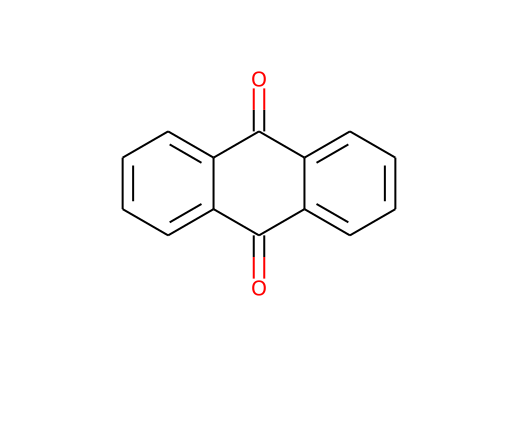

SMILES="C1=CC=C2C(=C1)C(=O)C3=CC=CC=C3C2=O";
pos_enc_dim=5;
res0 = pyrunfile("ChemMolFromSmiles.py","mol0",x=SMILES);
img0 = string(res0);
rgbImage0 = imread(img0);
imshow(rgbImage0)

### Convert SMILES to molecular graph

The following function uses RDKit to construct the molecular graph for the given SMILES structure. See the examples on [this page](https://www.rdkit.org/docs/GettingStartedInPython.html) to get started with the RDKit in Python. The adjacency and node matrices are stored in "graph_data.mat". 

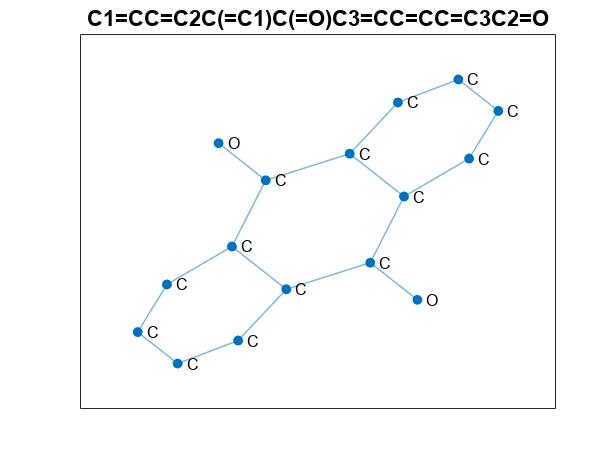

[molgraph,Adj,atomsymbols] = Graph_from_SMILES(SMILES);
figure, plot(molgraph, 'NodeLabel', atomsymbols, 'LineWidth', 0.75, 'Layout','force')
title(SMILES)

### Graph Laplacian

The normalized Laplacian matrix is obtained as $$\mathcal{L}=D^{-\frac{1}{2}}LD^{-\frac{1}{2}}$$, where $$\textit{L}$$ is the Laplacian matrix and $$\textit{D}=diag(d)$$ with $$\textit{d(i)}$$ is the degree of node i. We can then calculate the [eigenvalues and eigenvectors](https://www.mathworks.com/help/matlab/ref/eig.html). The Laplacian PE for each node is the k smallest non-trivial eigenvectors [4]. Below we extract these eigenvectors as "pos_vecs" and correcposing eigenvalues "pos_vals".

L = laplacian(molgraph);
LNorm = normalizeLaplacian(L,Adj);
k=pos_enc_dim;
[Vs,Ds] = eigs(LNorm,k,'smallestabs'); % This includes zero/trivial solution
V_pos = Vs(:,2:k); % This is to exclude the vector corresponding to zero
D_pos = diag(Ds);
pos_vals = D_pos(2:end)

pos_vals =     0.0637
    0.1674
    0.1785
    0.3619


pos_vecs = V_pos

pos_vecs =    -0.3589    0.0560   -0.3174   -0.2149
   -0.3589   -0.0560   -0.3174    0.2149
   -0.2903   -0.1399   -0.1474    0.4113
   -0.1921   -0.1773    0.1172    0.1861
   -0.1921    0.1773    0.1172   -0.1861
   -0.2903    0.1399   -0.1474   -0.4113
   -0.0000    0.4288    0.3209    0.0000
   -0.0000    0.4559    0.3530    0.0000
    0.1921    0.1773    0.1172    0.1861
    0.2903    0.1399   -0.1474    0.4113


`We can also `compute the Fiedler vector, which can be used to [partition the graph](https://www.mathworks.com/help/matlab/math/partition-graph-with-laplacian-matrix.html) into two subgraphs. The Fiedler vector is the eigenvector corresponding to the second smallest eigenvalue of the graph (The *smallest* eigenvalue is zero, indicating that the graph has one connected component).

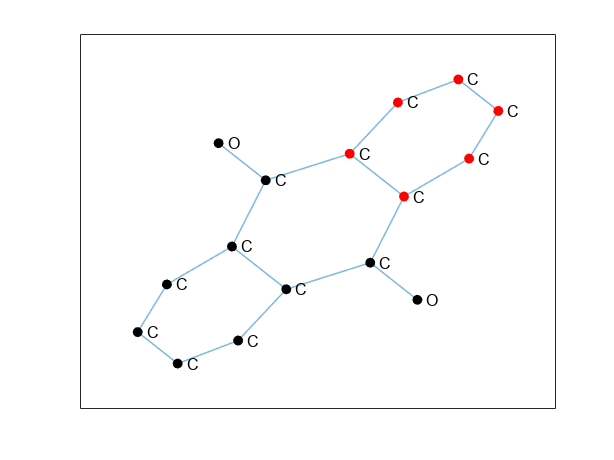

w = Vs(:,2);
p = plot(molgraph, 'NodeLabel', atomsymbols, 'LineWidth', 0.75, 'Layout','force');
highlight(p,find(w>=0),'NodeColor','r') % subgraph A
highlight(p,find(w<0),'NodeColor','k') % subgraph B

### References

[1] Mikhail Belkin and Partha Niyogi. Laplacian eigenmaps for dimensionality reduction and data representation. [Neural computation, 15(6):1373–1396, 2003](https://direct.mit.edu/neco/article-abstract/15/6/1373/6730/Laplacian-Eigenmaps-for-Dimensionality-Reduction?redirectedFrom=fulltext).

[2] Chengxuan Ying, et. al., Do Transformers Really Perform Bad for Graph Representation?, [2106.05234.pdf (arxiv.org)](https://arxiv.org/pdf/2106.05234.pdf).

[3] RDKit: Open-source cheminformatics; [http://www.rdkit.org](https://www.rdkit.org/)

[4] Grégoire Mialon, et.al., GraphiT: Encoding Graph Structure in Transformers, [2106.05667.pdf (arxiv.org)](https://arxiv.org/pdf/2106.05667.pdf).